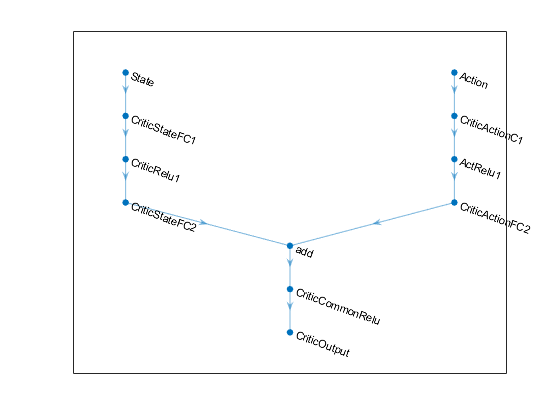

clc;clear;close all;
open_system('rlpitch2')
obsInfo = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf -inf]',...
    'UpperLimit',[ inf  inf inf]');

numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([3 1]);
numActions = actInfo.Dimension(1);
env = rlSimulinkEnv('rlpitch2','rlpitch2/RL Agent',...
    obsInfo,actInfo);
env.ResetFcn = @(in)localResetFcn(in);
Ts = 1;
Tf = 100;
rng(0)
statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(300,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(300,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1],'Normalization','none','Name','Action')
    fullyConnectedLayer(300,'Name','CriticActionC1')
    reluLayer('Name','ActRelu1')
    fullyConnectedLayer(300,'Name','CriticActionFC2')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC2','add/in2');
figure
plot(criticNetwork)
criticOpts = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);
critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(300,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1') 
    fullyConnectedLayer(300,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2') 
    fullyConnectedLayer(300,'Name','ActorFC3')
    reluLayer('Name','ActorRelu3') 
    fullyConnectedLayer(300,'Name','ActorFC4')
    reluLayer('Name','ActorRelu4') 
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-05,'GradientThreshold',1);

actor = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6);
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

maxepisodes = 10000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',999);

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('WaterTankDDPG.mat','agent')
end


%validation
resp={};
tgt=[];
times= {};
val_vals= 1.5*rand(1,10);
for i=1: length(val_vals)
    h = val_vals(i)
    blk = sprintf('rlpitch2/Desired \nPitch Angle');
    set_param(blk,'Value',num2str(h));
    simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
    experiences = sim(env,agent,simOpts);
    tgt=[tgt experiences.SimulationInfo.Desired];
    resp{end+1}= experiences.SimulationInfo.Actual;
    times{end+1}= experiences.SimulationInfo.tout;
    
end

h = 0.5853

h = 0.6503

h = 0.3030

h = 0.9463

h = 0.7194

h = 0.3045

h = 1.0562

h = 1.0746

h = 0.9750

h = 1.1066

function in = localResetFcn(in)

% randomize reference signal
blk = sprintf('rlpitch2/Desired \nPitch Angle');

h= (-1.5)+1.5*rand(1,1);
in = setBlockParameter(in,blk,'Value',num2str(h));


end

